%% PASO 1: TOPOGRAFÍA TORROELLA (FINAL)
clear; clc; close all;

filename = 'C:\Datos_Incendio\dem_torroella.asc'; 
output_mat = 'C:\Datos_Incendio\topography_torroella.mat';

fprintf('1. Procesando Topografía...\n');

1. Procesando Topografía...


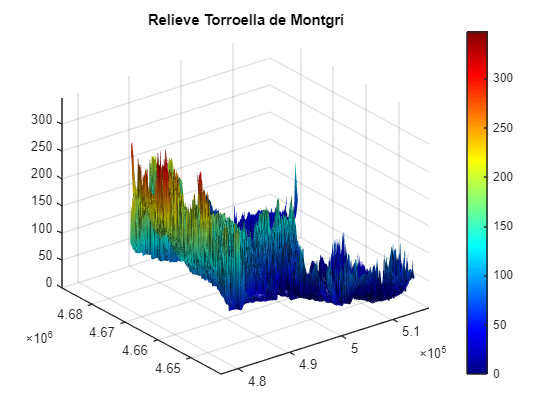

[Z, X, Y] = read_asc_robust(filename);

% --- FILTRADO DE ERRORES ---
% Convertir valores "NoData" (-9999) a NaN para que no rompan el gráfico
Z(Z < -100) = NaN; 

% Visualización
figure('Name', 'Topografía Torroella', 'Color', 'w');
surf(X, Y, Z); 
shading interp; colormap jet; 
camlight; lighting gouraud;
title('Relieve Torroella de Montgrí');
axis tight; view(3); colorbar;


save(output_mat, 'X', 'Y', 'Z'); 
fprintf('✅ Topografía guardada correctamente.\n');

✅ Topografía guardada correctamente.



% (Pega aquí la función read_asc_robust de siempre)
function [Data, X, Y] = read_asc_robust(filename)
    fid = fopen(filename, 'r');
    ncols=[]; nrows=[]; xll=[]; yll=[]; cellsize=[]; nodata=-9999;
    for i=1:6
        line=fgetl(fid); parts=strsplit(strtrim(line));
        key=lower(parts{1}); val=str2double(parts{end});
        if contains(key,'ncols'), ncols=val; end
        if contains(key,'nrows'), nrows=val; end
        if contains(key,'xll'), xll=val; end
        if contains(key,'yll'), yll=val; end
        if contains(key,'cell'), cellsize=val; end
        if contains(key,'nodata'), nodata=val; end
    end
    fclose(fid);
    Data = dlmread(filename, '', 6, 0);
    if size(Data,1)~=nrows || size(Data,2)~=ncols, Data=Data(1:nrows,1:ncols); end
    x_vec = xll + (0:ncols-1).*cellsize;
    y_vec = yll + (nrows-1:-1:0).*cellsize;
    [X, Y] = meshgrid(x_vec, y_vec);
end